% load amundsen variables for mesh
run illapel_amundsen_ice.m
addpath('../Amundsen/')
Size = length(w0);
%Wsmim = V1e3smim(1:Size,:);

% load evecs and evals
% load amundsen_smim1e3_V_D.mat

% plot the smallest absolute e-vals
load amundsen_smabs1e3_V_D.mat

Wsmabs = V1e3smabs(1:Size,:);

%k = 5;
%evcplt(D1e3smim(k),W(:,k),k,'smallestimag')

% plot the evals
%Dmx = max(abs(D1e3smim));

% plotting evals
% figure(1)
% ax1 = gca;
% ax1.XAxisLocation = 'origin';
% ax1.YAxisLocation = 'origin';
% axis on
% for i = 1:length(D1e3smim)
%     plot(real(D1e3smim(i)),imag(D1e3smim(i)),'x')
%     plot(real(D1e3smim(i)),-imag(D1e3smim(i)),'o',Color='white')
%     hold on
% end
% grid on
% clim([-Dmx Dmx]);
% hold off
% title("Amundsen 1000 smallest imaginary e-vals")
% %subtitle("(black circles are generated)")
% exportgraphics(ax1,"am1000smim.png");

%Dmxa = max(abs(D1e3smabs));

%%% Plotting evals %%%
% figure(2)
% ax2 = gca;
% ax2.XAxisLocation = 'origin';
% ax2.YAxisLocation = 'origin';
% axis on
% 
% for i = 1:length(D1e3smabs)
%     plot(real(D1e3smabs(i)),imag(D1e3smabs(i)),'x')
%     plot(-real(D1e3smabs(i)),imag(D1e3smabs(i)),'x',Color='white')
%     hold on
% end
% grid on
% clim([-Dmxa Dmxa]);
% hold off
% title("Amundsen 1000 smallest absolute e-vals")
% exportgraphics(ax1,"am1000smabs.png");

%%% Now Eigenvectors %%%

% try the function "in line"

k = 15;

% evcplt(D1e3smabs(k),Wsmabs(:,k),k,'smallestabs')

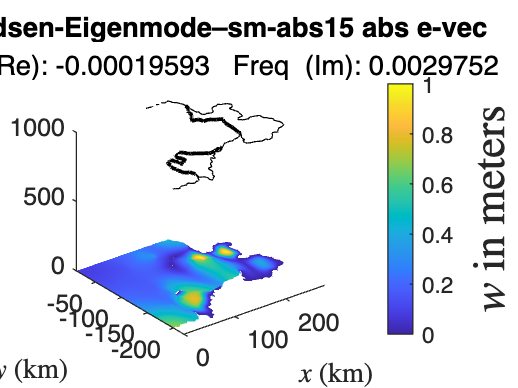

% given a complex eval - evec pair s, w
% generates three figures for a normalized w
% real(w); imag(w); abs(w);
% with real(s) and im(s) in the title of the figures
s = D1e3smabs(k);
w = Wsmabs(:,k);
% set titles for the figure
ptitle = ['Amundsen-Eigenmode–','sm-abs',num2str(k),' abs e-vec'];

freqtitle = ['Decay (Re): ',num2str(real(s)),...
    '   Freq  (Im): ',num2str(imag(s))];

% normalize w
w = w / max(abs(w));

figure(k)
%subplot(2,2,1)
% plot abs(w)
colormap(parula)
for i = 1:length(g_ice.boundaryGroups.FR)
    free_coord = g.getBoundary(g_ice.boundaryGroups.FR(i));
    p1 = plot3(free_coord(:, 1), free_coord(:, 2), 1000 + 0*free_coord(:, 1), 'black-', 'LineWidth', 1.5);
    uistack(p1, 'top')                        
    hold on
end
for i = 1:length(g.boundaryGroups.R)
    reflectN = g.getBoundary(g.boundaryGroups.R(i));
    p2 = plot3(reflectN(:, 1), reflectN(:, 2), 1000 + 0*reflectN(:, 1), 'black-', 'LineWidth', 0.5);
    uistack(p2, 'top')
    hold on
end

xlabel('$x$ (km)', 'Interpreter', 'latex')
ylabel('$y$ (km)', 'Interpreter', 'latex')
xlim([plot_details.left, plot_details.right])
ylim([plot_details.bottom, plot_details.top])

%this is where the abs is taken
ph = multiblock.Surface(g, abs(w));
clim([0 1])

c = colorbar;
c.Label.String = '$w$ in meters';
c.Label.Interpreter = 'latex';
c.Label.FontSize = 18;
ph.set('LineStyle', 'none');
ph.set('FaceColor', 'interp');

ph.CData = abs(w);
ph.ZData = abs(w);

title(ptitle)
subtitle(freqtitle)


% % plot Re(w)
% subplot(2,2,2)
% cmap 
% for i = 1:length(g_ice.boundaryGroups.FR)
%     free_coord = g.getBoundary(g_ice.boundaryGroups.FR(i));
%     p1 = plot3(free_coord(:, 1), free_coord(:, 2), 1000 + 0*free_coord(:, 1), 'black-', 'LineWidth', 1.5);
%     uistack(p1, 'top')                        
%     hold on
% end
% for i = 1:length(g.boundaryGroups.R)
%     reflectN = g.getBoundary(g.boundaryGroups.R(i));
%     p2 = plot3(reflectN(:, 1), reflectN(:, 2), 1000 + 0*reflectN(:, 1), 'black-', 'LineWidth', 0.5);
%     uistack(p2, 'top')
%     hold on
% end
% 
% xlabel('$x$ (km)', 'Interpreter', 'latex')
% ylabel('$y$ (km)', 'Interpreter', 'latex')
% xlim([plot_details.left, plot_details.right])
% ylim([plot_details.bottom, plot_details.top])
% 
% % this is where the abs is taken
% ph = multiblock.Surface(g, real(w));
% clim([-1 1])
% 
% c = colorbar;
% c.Label.String = '$w$ in meters';
% c.Label.Interpreter = 'latex';
% c.Label.FontSize = 18;
% ph.set('LineStyle', 'none');
% ph.set('FaceColor', 'interp');
% 
% ph.CData = real(w);
% ph.ZData = real(w);

